# TREESELECT

Perform feature selection on the heart disease data using built-in methods of a decision tree model. 

## Load data

load heartdisease

## Perform feature selection

Perform feature selection on a decision tree model for the heart disease data.

m = fitctree(heartdataNum,'HeartDisease');

Obtain the importance of the individual predictors.

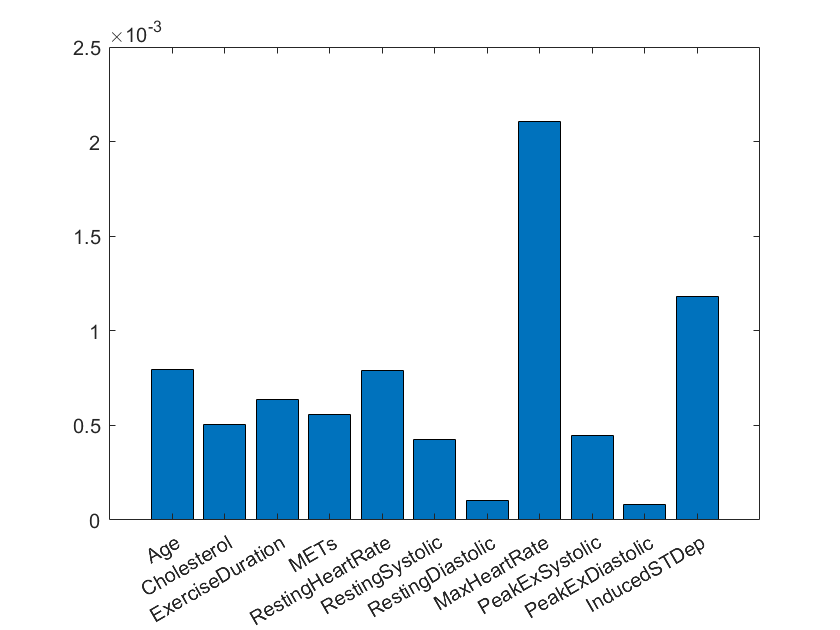

p = predictorImportance(m);
bar(p)
xticklabels(vars)

## Threshold to find the relevant variables

tokeep = (p > 0.1*max(p));
vars(tokeep)

ans = 1×9 cell array
    {'Age'}    {'Cholesterol'}    {'ExerciseDuration'}    {'METs'}    {'RestingHeartRate'}    {'RestingSystolic'}    {'MaxHeartRate'}    {'PeakExSystolic'}    {'InducedSTDep'}


## Compare the full and reduced models

HD = heartdataNum.HeartDisease;
rng(1234)
part = cvpartition(HD,'KFold',10); 

Create the full model

m = fitctree(numdata(:,tokeep),HD,'CVPartition',part);
kfoldLoss(m)

ans = 0.3630

Create the reduced model

m = fitctree(numdata,HD,'CVPartition',part);
kfoldLoss(m)

ans = 0.3583